clc, clear, clf;
dy=@(x,y,z) z;
dz=@(x,y,z) 2*y-3*z;
x(1)=0;
z(1)=1;
y(1)=x;
h=0.1;
xfinal=2;
N=ceil((xfinal-x(1))/h);

for j=1:N
    x(j+1)=x(j)+h;
    k1y=dy(x(j),y(j),z(j));
    k1z=dz(x(j),y(j),z(j));
    k2y=dy(x(j)+h/2,y(j)+h/2*k1y,z(j)+h/2*k1z);
    k2z=dz(x(j)+h/2,y(j)+h/2*k1y,z(j)+h/2*k1z);
    k3y=dy(x(j)+h/2,y(j)+h/2*k2y,z(j)+h/2*k2z);
    k3z=dz(x(j)+h/2,y(j)+h/2*k2y,z(j)+h/2*k2z);
    k4y=dy(x(j)+h,y(j)+h*k3y,z(j)+h*k3z);
    k4z=dz(x(j)+h,y(j)+h*k3y,z(j)+h*k3z);
    y(j+1)=y(j)+h/6*(k1y+2*k2y+2*k3y+k4y);
    z(j+1)=z(j)+h/6*(k1z+2*k2z+2*k3z+k4z);
end

disp(y(N));

    0.7047



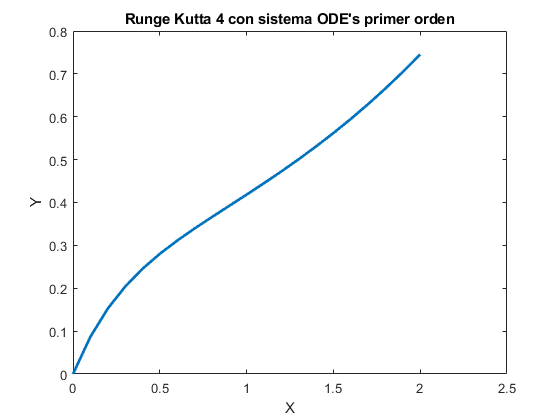

figure;
plot(x,y,'LineWidth',2);
xlabel('X');
ylabel('Y');
title('Runge Kutta 4 con sistema ODE''s primer orden')

clear, clc, clf;

syms t

current=(sin(10*t)/2)-(5*exp(1)^(-6*t)*sin(8*t)/8)

$$current = \frac{\sin\left(10\,t\right)}{2}-\frac{5\,\sin\left(8\,t\right)}{8\,{\left(\frac{3060513257434037}{1125899906842624}\right)}^{6\,t}}$$

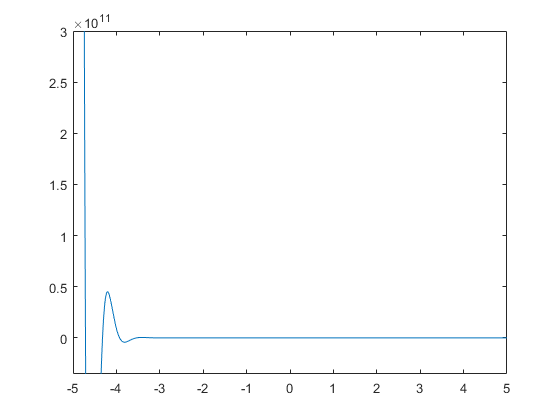


fplot(current)


charge=(-cos(2*t)/20)-(5/8)*(exp(1)^(-6*t)*(-6*sin(8*t)-8*cos(8*t))/100)

$$charge = \frac{8\,\cos\left(8\,t\right)+6\,\sin\left(8\,t\right)}{160\,{\left(\frac{3060513257434037}{1125899906842624}\right)}^{6\,t}}-\frac{\cos\left(2\,t\right)}{20}$$

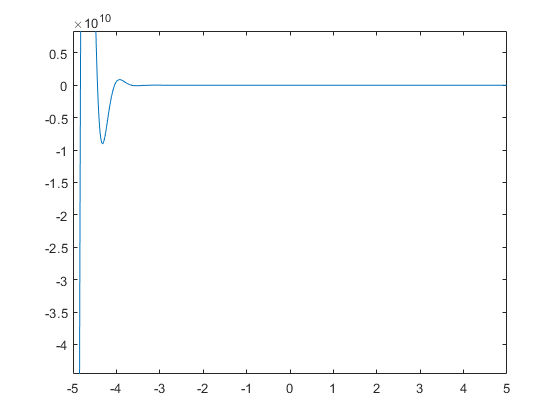


fplot(charge)


current1=1.51*cos(10*t+52.69)

$$current1 = \frac{151\,\cos\left(10\,t+\frac{5269}{100}\right)}{100}$$

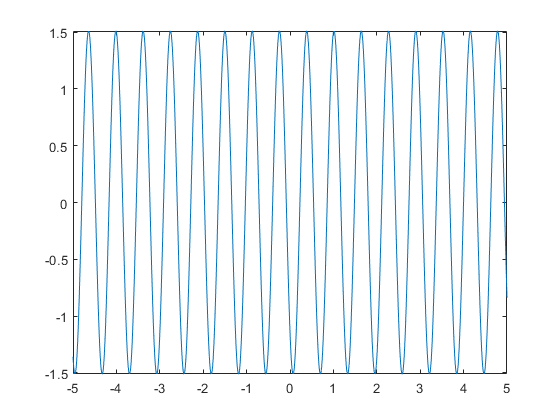


fplot(current1)


charge1=0.151*(sin(10*t+52.69)-0.795)

$$charge1 = \frac{151\,\sin\left(10\,t+\frac{5269}{100}\right)}{1000}-\frac{24009}{200000}$$

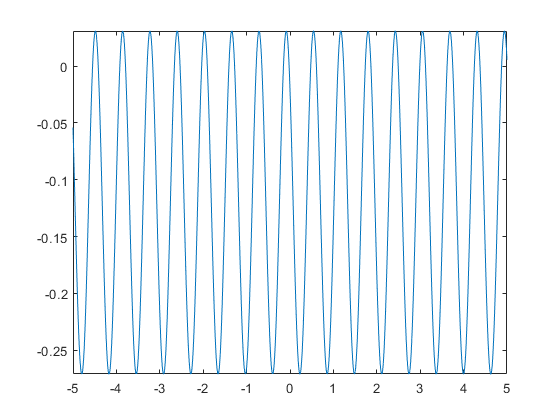


fplot(charge1)